% Erivelton Gualter 

clear all
close all
clc


**Question 1:**

% Ax>=b
A = [1 1 1; 0 0 -1; 0 -1 0; -1 0 0]; 
B = [4; -2; 0; -4];

P = diag([2 4 8]);
xc = [1 1 1]';
f = -xc'*P;

hold on;
E = ellipsoid(xc, P);

Initializing Ellipsoidal Toolbox version 1.1.2 ...


plot(E,'b');

Plotting ellipsoid...


Hyperplane Plots

% Form hyperplane array (box constraints)
HA1 = hyperplane(A(1,:)',B(1));
HA2 = hyperplane(-A(2,:)',-B(2));
HA3 = hyperplane(-A(3,:)',-B(3));
HA4 = hyperplane(-A(4,:)',-B(4));

plot(HA1,'r');

Plotting hyperplane...


plot(HA2,'g');

Plotting hyperplane...


plot(HA3,'b');

Plotting hyperplane...


plot(HA4,'c');

Plotting hyperplane...



axis([-4 4 -4 4 -4 4]);

x0 = [3.5 -0.5 2]';
Xr = x0; 

if (A*x0-B) > 0
    disp('x0 Ok');
end

% Constraints 1
A2=A(2,:);
Z=null(A2);

g = P*x0 + f';
pz=-(Z'*P*Z)\(Z'*g);
p0=Z*pz;

xtest=x0+p0;
if (A*x0-B) > 0
    disp('xteste Ok');
else
    disp('xteste not Ok');
end

xteste not Ok



alph_max3=(B(3)-A(3,:)*x0)/(A(3,:)*p0);
alph_max=alph_max3;
x1=x0+alph_max*p0;

Xr = [Xr x1]; 

% Constraints 2
A3=A(3,:);
Z=null(A3);

g = P*x1 + f';
pz=-(Z'*P*Z)\(Z'*g);
p1=Z*pz;

xtest=x1+p1;
if (A*x0-B) > 0
    disp('xteste Ok');
else
    disp('xteste not Ok');
end

xteste not Ok



alph_max1=(B(1)-A(1,:)*x1)/(A(1,:)*p1);
alph_max=alph_max1;
x2=x1+alph_max*p1;

Xr = [Xr x2];

% Constraints 3
A14=A([1 4],:);
Z=null(A14);

g = P*x2 + f';
pz=-(Z'*P*Z)\(Z'*g);
p2=Z*pz;

xtest=x2+p2;
if (A*x0-B) > 0
    disp('xteste Ok');
else
    disp('xteste not Ok');
end

xteste not Ok


alph_max4=(B(4)-A(4,:)*x2)/(A(4,:)*p2);
alph_max1=(B(1)-A(1,:)*x2)/(A(1,:)*p2);
alph_max3=(B(3)-A(3,:)*x2)/(A(3,:)*p2);
alph_max=min(alph_max1,alph_max3);
x3=x2+alph_max*p2;

plot3(x0(1),x0(2),x0(3),'ok');
plot3(x1(1),x1(2),x1(3),'*k');
plot3(x2(1),x2(2),x2(3),'*k')
plot3(Xr(1,:), Xr(2,:), Xr(3,:),'LineWidth',3)


Solution Using **quadprog**:

X = quadprog(P,f,-A,-B);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<

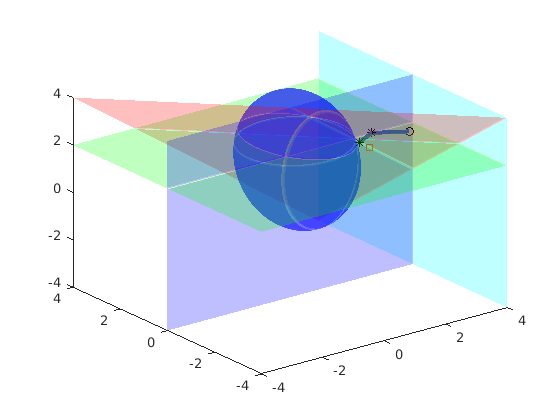

plot3(X(1),X(2),X(3),'s');

**Question 2: **

H = P;
g = f;
lb = [];
ub = [];
lbA = [];
ubA = B;

x = qpOASES( H,g',-A,lb,ub,[],-ubA )

x =     2.6000
         0
    1.4000
